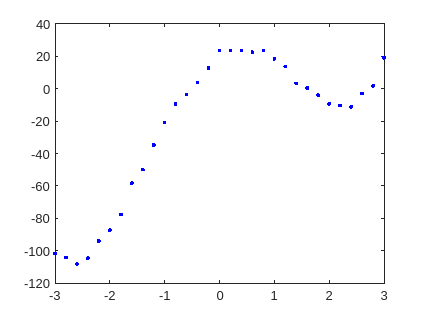

data = [-3.0000 -101.6943
        -2.8000 -104.2142
        -2.6000 -108.2620
        -2.4000 -104.6402
        -2.2000 -94.0569
        -2.0000 -87.2916
        -1.8000 -77.6506
        -1.6000 -58.3214
        -1.4000 -49.9176
        -1.2000 -34.8374
        -1.0000 -20.7974
        -0.8000 -9.3930
        -0.6000 -3.6132
        -0.4000  3.8674
        -0.2000  12.7480
         0       23.6752
         0.2000  23.5968
         0.4000  23.6975
         0.6000  22.5622
         0.8000  23.5591
         1.0000  18.5392
         1.2000  13.7245
         1.4000  3.2934
         1.6000  0.4310
         1.8000 -3.9539
         2.0000 -9.2467
         2.2000 -10.3451
         2.4000 -11.2206
         2.6000 -2.8333
         2.8000  1.7706
         3.0000  19.1156];

x = data(:,1);
y = data(:,2);

plot(x,y,'b.');

**a) Find the nonlinear regression function given by the nonlinear epsilon-SV using a polynomial kernel with p = 4 and parameters epsilon = 10, C = 10.**

**b) Find the support vectors.**

p = 4;
epsilon = 10;
C = 10;
l = length(x1);

l = length(x) ; % number of points

%% nonlinear regression - dual problem

epsilon = 10 ;
C = 10;

% define the problem
X = zeros(l,l);
for i = 1 : l
    for j = 1 : l
        X(i,j) = kernel(x(i),x(j)) ;
    end
end
Q = [ X -X ; -X X ];   
c = epsilon*ones(2*l,1) + [-y;y]; 

% solve the problem
sol = quadprog(Q,c,[],[],...
    [ones(1,l) -ones(1,l)],0,...
    zeros(2*l,1),C*ones(2*l,1));


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


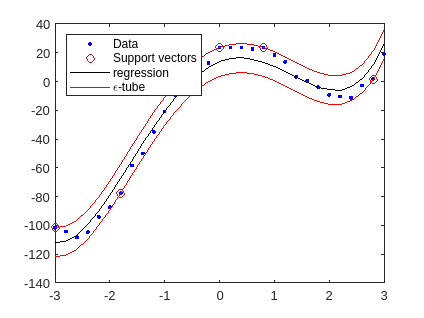

lap = sol(1:l);
lam = sol(l+1:2*l);

% compute b
ind = find(lap > 1e-3 & lap < C-1e-3);
if ~isempty(ind)
    i = ind(1);
    b = y(i) - epsilon;
    for j = 1 : l
        b = b - (lap(j)-lam(j))*kernel(x(i),x(j));
    end
else
    ind = find(lam > 1e-3 & lam < C-1e-3);
    i = ind(1);
    b = y(i) + epsilon ;
    for j = 1 : l
        b = b - (lap(j)-lam(j))*kernel(x(i),x(j));
    end
end

% find regression and epsilon-tube
z = zeros(l,1);
for i = 1 : l
    z(i) = b ;
    for j = 1 : l
        z(i) = z(i) + (lap(j)-lam(j))*kernel(x(i),x(j));
    end
end
zp = z + epsilon ;
zm = z - epsilon ;

%% plot the solution

% find support vectors
sv = [find(lap > 1e-3);find(lam > 1e-3)]; 
sv = sort(sv);

plot(x,y,'b.',x(sv),y(sv),...
    'ro',x,z,'k-',x,zp,'r-',x,zm,'r-');

legend('Data','Support vectors',...
    'regression','\epsilon-tube',...
    'Location','NorthWest')



disp(x(sv))

   -3.0000
   -1.8000
         0
    0.8000
    2.8000



disp(y(sv))

 -101.6943
  -77.6506
   23.6752
   23.5591
    1.7706




%% kernel function


function v = kernel(x,y)

p = 4 ;
v = (x'*y + 1)^p;

end

